# Explore a few ideas for signal enhancement using raw samples

clear; close all; clc; rng(0)

## Create datastore to source raw data automatically

Create datastore to read speaker response segments.

We use data from the "samples" folder because this unprocessed and generally harder to get, but the same principles can be applied more easily also to the enroll and test data

dataloc = 'C:\Users\nidul\Desktop\ACCA Folder My\Signal processing cup\ROBOVOX_SP_CUP_2024\';
locraw = fullfile(dataloc,'samples');

This datastore returns the original 8-channel recordings with the complete set of original labels

rawds = getRawSamplesDatastore(locraw);

'getRawSamplesDatastore' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\nidul\Desktop\ACCA Folder My\Signal processing cup\MATLAB

Change the MATLAB current folder or add its folder to the MATLAB path.

This datastore returns only the regions with speaker reponses for channels 4 and 5

segsds = transform(rawds,@getSampleSegments,IncludeInfo=true);
shuffle(segsds);

Inspect segments from individual recordings

[x,info] = read(segsds)

x = 1×6 cell array
    {49291×2 double}    {59767×2 double}    {61593×2 double}    {34095×2 double}    {40699×2 double}    {121619×2 double}


info = struct with fields:
       SampleRate: 16000
         FileName: 'C:\Users\gbunkhei\Downloads\ROBOVOX_SP_CUP\ROBOVOX_SP_CUP_2024\data\samples\1_1_0_1\sound.wav'
            Label: [1×3 table]
    ChannelLabels: ["Channel4"    "Channel5"]


fs = info.SampleRate;

probeSegment = 5

probeSegment = 5

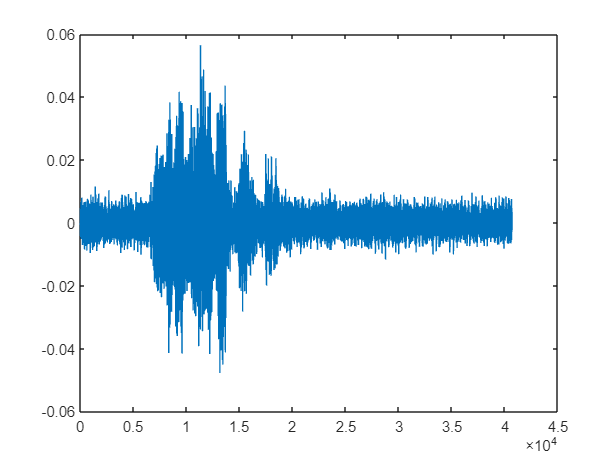

y = x{probeSegment}(:,1); % Channel 4
plot(y)

soundsc(y,fs)
% audiowrite("noisytest.wav",y,fs);

## How to use an audio enhancement effect available as VST or AU plugin?

Local path of plugin binary - note that this plugin may not be commercially 

erapath = "C:\Program Files\Steinberg\VstPlugins\Accusonus";

The real-time processing loop allows to interactively identify a good set of operating parameters

blockLen = 1024; % samples per frame

Objects to read from audio file and write to audio device in streaming mode

testfile = "noisytest_bu.wav";
fr = dsp.AudioFileReader(testfile,"SamplesPerFrame",blockLen,"PlayCount",50);
adw = audioDeviceWriter(fs);

Host (import) external VST plugin to use it as MATLAB object

eranr = loadAudioPlugin(fullfile(erapath,"ERA6_NoiseRemover.dll"));
setSampleRate(eranr,fs)

Auto-generate a MATLAB UI to tune the audio plugi parameters interactively

tunnr = parameterTuner(eranr);

Adjust parameters interactively as audio is played

while ishandle(tunnr) && ~isDone(fr)
    % Read buffer from audio segment
    auin = fr();

    % Cleanup buffer - note the plugin requires a stereo signal
    auout = process(eranr,repmat(auin,1,2));

    % Write cleaned-up buffer to audio device
    adw(auout(:,1));

    % TO NOT FORGET - Flush graphics pipeline while looping through audio
    drawnow limitrate
end

Apply plugin effect on full sample once we are happy with reults

[y,fs] = audioread(testfile)

fs = 16000

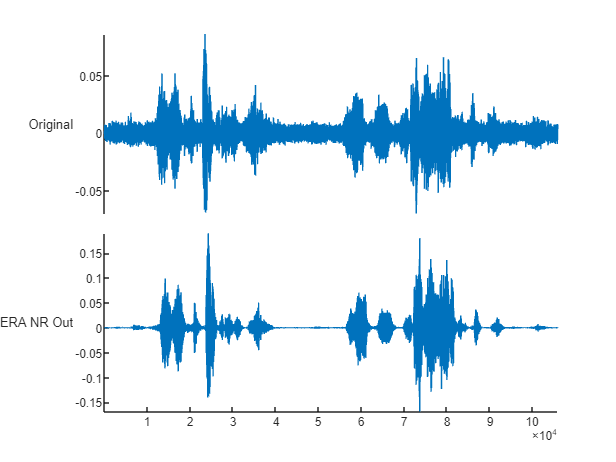

in = repmat(y,1,2);
setMaxSamplesPerFrame(eranr, 1e6);
out = process(eranr,in)
sp = stackedplot([y, out(:,1)]);
sp.DisplayLabels = {'Original';'ERA NR Out'};

soundsc([y; out(:,1)],fs)

Enhance via AI-based source separation model

ys = separateSpeakers(y,fs,NumSpeakers=2);
size(ys)
soundsc([y;ys(:)],fs)

[ys2,r] = separateSpeakers(y,fs);
size(ys)
soundsc([y;ys2(:);r],fs)

## Voice Activity Detection and Speaker Segmentation

Using traditional signal processing methods can be hard with high noise floors

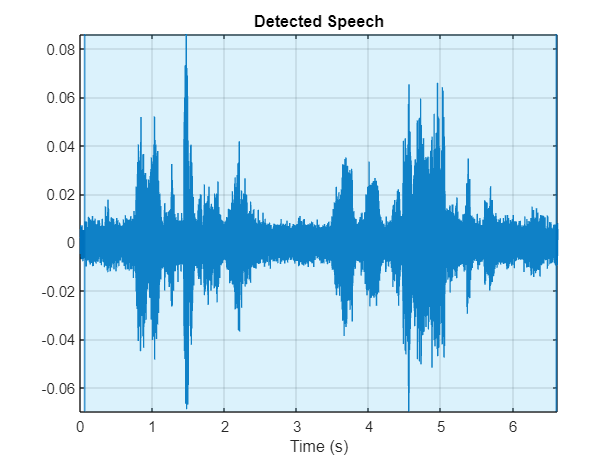

detectSpeech(y(:,1),fs)

...but easier once noise is removed

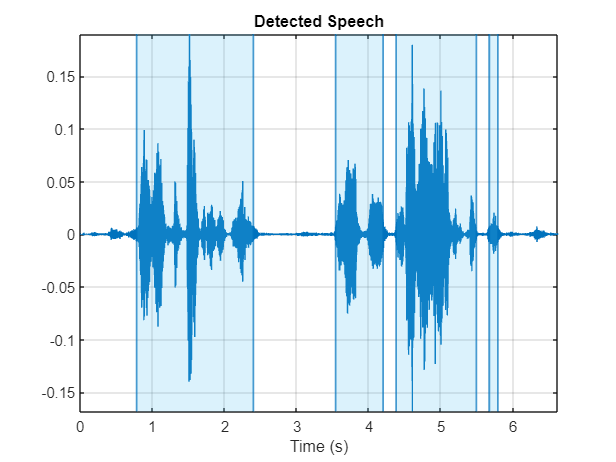

detectSpeech(out(:,1),fs)

Save results

VADidx = detectSpeech(out(:,1),fs);
onesecpause = zeros(fs,1);
segcleany = zeros(0,1);
for kseg = 1:size(VADidx,1)
    segcleany = [segcleany; out(VADidx(kseg,1):VADidx(kseg,2),1)]; %#ok<AGROW>
    segcleany = [segcleany; onesecpause]; %#ok<AGROW>
end
% audiowrite("segmentedcleansample.wav",segcleany,fs)

AI-based methods generally prove more robust with respect to background noise

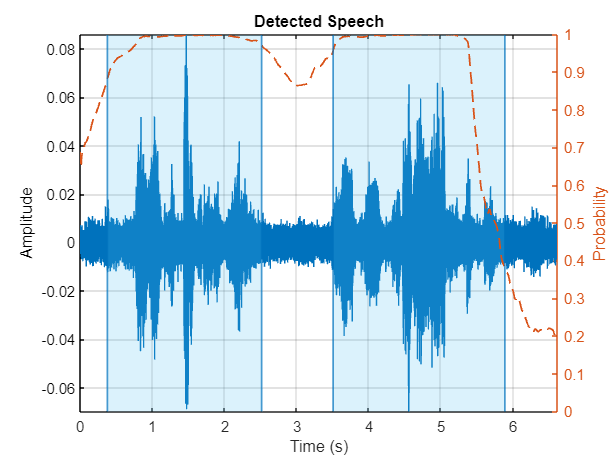

detectspeechnn(y(:,1),fs,ApplyEnergyVAD=true)

Save results

VADidx = detectspeechnn(y(:,1),fs,ApplyEnergyVAD=true);
onesecpause = zeros(fs,1);
segcleany = zeros(0,1);
for kseg = 1:size(VADidx,1)
    segcleany = [segcleany; out(VADidx(kseg,1):VADidx(kseg,2),1)]; %#ok<AGROW>
    segcleany = [segcleany; onesecpause]; %#ok<AGROW>
end
% audiowrite("segmentedcleansample.wav",segcleany,fs)

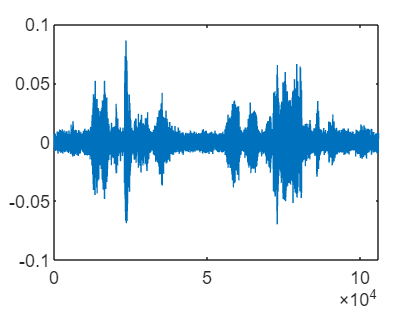

origfile = "noisytest_bu.wav";
[origy, fs] = audioread(origfile);
figure
plot(origy)

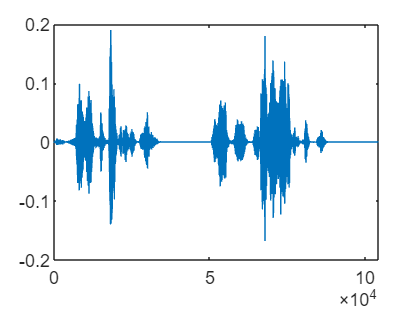

segcleanfile = "segmentedcleansample.wav";
[segcleany, fs] = audioread(segcleanfile);
figure
plot(segcleany)

soundsc([origy;segcleany],fs)

*Copyright 2023 The MathWorks, Inc.*